# Data preparation

clear; clc; close all;
warning('off');

% If no dataset, download it.
url = 'https://nextcloud.centralesupelec.fr/s/7AR6aamBZNXcRM8/download';
downloadFolder = fullfile('../', 'dataset');
rootDict = fullfile('../');
if ~exist(downloadFolder, 'dir')
    options = weboptions('Timeout', 30);
    loc = websave([downloadFolder '.zip'], url, options);
    unzip(loc, rootDict);
end

% Define training dan testing dataset.
trainingDataFolderName = '20241017';
testDataFolderName = '20241016';

mdlName = ['mdlTrajCmdTrajResidual' 'TrData' trainingDataFolderName 'TestData' testDataFolderName '.mat'];
% Define the path to check for 'conc_dataset.mat'
pathLoggedTrainingData = ['../dataset/trainingDatasets/' trainingDataFolderName '/training_dataset.mat'];
pathTrainingData = ['../dataset/trainingDatasets/' trainingDataFolderName '/'];

% Define a DataLoader instance.
% Define the length of simulation and the corresponding sequence length.
lenSeries = 1000; % Sequence length.
simulationTime = 10; % The time that this sequence corresponds to.
dataLoader = DataLoader(lenSeries, simulationTime);
dataLoader.shuffle = false; % Shuffle the data.
dataLoader.pathTrainingDataset = pathTrainingData;
dataLoader.pathLoggedTrainingData = pathLoggedTrainingData;
[X, y] = dataLoader.loadTrainingData();

Loaded data from ../dataset/trainingDatasets/20241017/training_dataset.mat


% Load test data
dataLoader.pathLoggedTestData = ['../dataset/testDatasets/' testDataFolderName '/real_testing_dataset.mat'];
dataLoader.pathTestDataset = ['../dataset/testDatasets/' testDataFolderName '/'];
dataLoader.pathOriginalTestData = ['../dataset/testDatasetsOriginal/' testDataFolderName '/'];
dataLoader.nTrajPerLabelTestDataset = 10;
dataLoader.labelList = {'Healthy', ...
    'Motor_1_Stuck', 'Motor_2_Stuck', 'Motor_3_Stuck', 'Motor_4_Stuck', ...
    'Motor_1_Steady_state_error', 'Motor_2_Steady_state_error', 'Motor_3_Steady_state_error', 'Motor_4_Steady_state_error'};
[X_test, y_test] = dataLoader.loadTestingData();

Loaded data from ../dataset/testDatasets/20241016/real_testing_dataset.mat


y_test = categorical(y_test);

# Original features

Train an LSTM with the orginal features: Commands on motors 1-4, and the measured $x, y, z$ coordiantes of the end-effector. Repeat the experiment $5$ times. 

X_orgFeatures = dataLoader.extractFeaturesOriginal(X);
X_test_orgFeatures = dataLoader.extractFeaturesOriginal(X_test);

randSeedInitial = 42;
n_experiment = 5;
epochs = 10:10:50;
n_epochs = length(epochs);

results_tr_org = cell(n_epochs, n_experiment);
results_val_org = cell(n_epochs, n_experiment);
results_test_org = cell(n_epochs, n_experiment);

tic;
for k = 1:n_epochs
    maxEpochs = epochs(k);
    fprintf('Maxi Epoch: %d\n', maxEpochs);
    for i = 1:n_experiment
        fprintf('%d/%d\n', i, n_experiment);
    
        randSeed = randSeedInitial+i-1;
        [result_tr, result_val, result_test] = runExperiment(X_orgFeatures, X_test_orgFeatures, y, y_test, dataLoader, randSeed, maxEpochs);
        
        results_tr_org{k, i} = result_tr;
        results_val_org{k, i} = result_val;
        results_test_org{k, i} = result_test;
    end
end

Maxi Epoch: 10


1/5
2/5
3/5
4/5
5/5


Maxi Epoch: 20


1/5
2/5
3/5
4/5
5/5


Maxi Epoch: 30


1/5
2/5
3/5
4/5
5/5


Maxi Epoch: 40


1/5
2/5
3/5
4/5
5/5


Maxi Epoch: 50


1/5
2/5
3/5
4/5
5/5


elaspedTimeOrg = toc

elaspedTimeOrg = 2.7143e+03

# Augumented features

X_augFeatures = dataLoader.extractFeaturesTrajCmdTrajResidual(X);
X_test_augFeatures = dataLoader.extractFeaturesTrajCmdTrajResidual(X_test);

results_tr_aug = cell(n_epochs, n_experiment);
results_val_aug = cell(n_epochs, n_experiment);
results_test_aug = cell(n_epochs, n_experiment);

tic;
for k = 1:n_epochs
    maxEpochs = epochs(k);
    fprintf('Maxi Epoch: %d\n', maxEpochs);
    for i = 1:n_experiment
        fprintf('%d/%d\n', i, n_experiment);
    
        randSeed = randSeedInitial+i-1;
        [result_tr, result_val, result_test] = runExperiment(X_augFeatures, X_test_augFeatures, y, y_test, dataLoader, randSeed, maxEpochs);
        
        results_tr_aug{k, i} = result_tr;
        results_val_aug{k, i} = result_val;
        results_test_aug{k, i} = result_test;
    end
end

Maxi Epoch: 10


1/5
2/5
3/5
4/5
5/5


Maxi Epoch: 20


1/5
2/5
3/5
4/5
5/5


Maxi Epoch: 30


1/5
2/5
3/5
4/5
5/5


Maxi Epoch: 40


1/5
2/5
3/5
4/5
5/5


Maxi Epoch: 50


1/5
2/5
3/5
4/5
5/5


elaspedTimeAug = toc

elaspedTimeAug = 2.8893e+03


save('results.mat', 'results_tr_org', 'results_tr_aug', 'results_val_aug', 'results_test_aug', 'results_test_org', 'results_val_org');

# Post-processing

First, we compare the performance of using the original features (commands for motors 1-4) and trajctory resposne of the end-effector (x, y z) with that of the augumented features (trajectory response + residuals on x, y, z).

- Training and validation accuracy V.S. terminated epochs

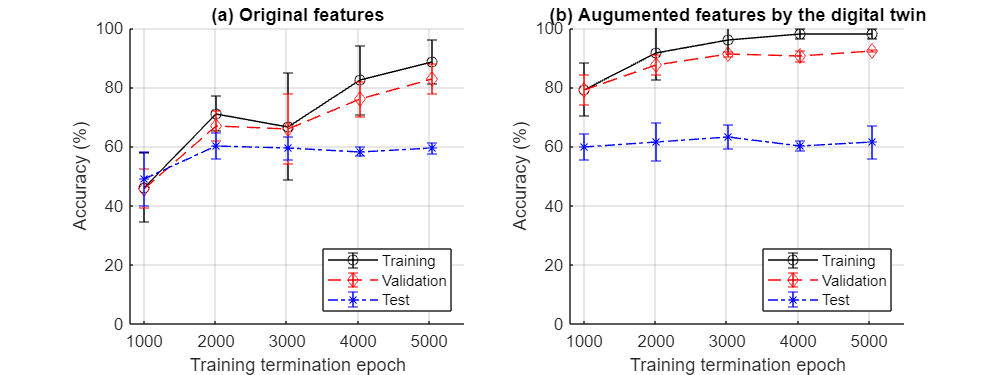

load('results.mat');

[meanAccTrOrg, stdAccTrOrg] = processTrainingAcc(results_tr_org);
[meanAccTrAug, stdAccTrAug] = processTrainingAcc(results_tr_aug);

[meanAccValOrg, stdAccValOrg, indexesValOrg] = processValidationAcc(results_val_org);
[meanAccValAug, stdAccValAug, indexesValAug] = processValidationAcc(results_val_aug);

[meanAccTestOrg, stdAccTestOrg, otherPerfsOrg] = processTestPerfs(results_test_org);
[meanAccTestAug, stdAccTestAug, otherPerfsAug] = processTestPerfs(results_test_aug);
% Transfer to percentage.
for i = 1:length(meanAccTestOrg)
    meanAccTestOrg{i} = meanAccTestOrg{i}*100;
    meanAccTestAug{i} = meanAccTestAug{i}*100;
    stdAccTestOrg{i} = stdAccTestOrg{i}*100;
    stdAccTestAug{i} = stdAccTestAug{i}*100;
end

% Define figure size in pixels
width = 800;
height = 300;

figure('Position', [100, 100, width, height]);
subplot(1, 2, 1);  % 1 row, 2 columns, first subplot
plotTrPerfs(meanAccTrOrg, stdAccTrOrg, 'ko-')
plotValPerfs(meanAccValOrg, stdAccValOrg, indexesValOrg, 'rd--')
plotValPerfs(meanAccTestOrg, stdAccTestOrg, indexesValOrg, 'b*-.')
xlabel('Training termination epoch');
ylabel('Accuracy (%)');
title('(a) Original features')
legend('Training', 'Validation', 'Test', 'Location', 'southeast')
grid on

subplot(1, 2, 2);  % 1 row, 2 columns, second subplot
plotTrPerfs(meanAccTrAug, stdAccTrAug, 'ko-')
plotValPerfs(meanAccValAug, stdAccValAug, indexesValAug, 'rd--')
plotValPerfs(meanAccTestAug, stdAccTestAug, indexesValOrg, 'b*-.')
xlabel('Training termination epoch');
ylabel('Accuracy (%)');
title('(b) Augumented features by the digital twin')
legend('Training', 'Validation', 'Test', 'Location', 'southeast')

% Set the y-axis limits to be the same for both subplots
subplot(1, 2, 1); xlim([800, 5500]); ylim([0, 100]);  % First subplot
subplot(1, 2, 2); xlim([800, 5500]); ylim([0, 100]);  % Second subplot
grid on

2. Print the precision, recall and f1 score for each class: Original features.

trainingAcc = meanAccTrOrg{end}(end);
trainingAccStd = stdAccTrOrg{end}(end);
validationAcc = meanAccValOrg{end}(end);
validationAccStd = stdAccValOrg{end}(end);
testAcc = meanAccTestOrg{end}(end);
testAccStd = stdAccTestOrg{end}(end);

precision = otherPerfsOrg.meanPrecision(end, :);
stdPrecision = otherPerfsOrg.stdPrecision(end, :);
recall = otherPerfsOrg.meanRecall(end, :);
stdRecall = otherPerfsOrg.stdRecall(end, :);
f1Score =  otherPerfsOrg.meanF1(end, :);
stdF1 = otherPerfsOrg.stdF1(end, :);

class_names = categories(y_test);

fprintf('Training Accuracy: %.2f%%+-%.2f%%\n', trainingAcc, trainingAccStd);

Training Accuracy: 88.75%+-7.53%


fprintf('Validation Accuracy: %.2f%%+-%.2f%%\n', validationAcc, validationAccStd);

Validation Accuracy: 83.00%+-5.13%


fprintf('Test Accuracy: %.2f%%+-%.2f%%\n\n', testAcc, testAccStd);

Test Accuracy: 59.56%+-1.86%




for i = 1:numel(class_names)   
    fprintf('Class %d (%s): Precision = %.2f+-%.2f, Recall = %.2f+-%.2f, F1 Score = %.2f+-%.2f\n', ...
        i, class_names{i}, ...
        precision(i), stdPrecision(i),...
        recall(i), stdRecall(i), ...
        f1Score(i), stdF1(i));
end

Class 1 (Healthy): Precision = 0.28+-0.44, Recall = 0.06+-0.09, F1 Score = NaN+-NaN
Class 2 (Motor_1_Steady_state_error): Precision = 0.43+-0.07, Recall = 0.18+-0.04, F1 Score = 0.25+-0.06
Class 3 (Motor_1_Stuck): Precision = 0.58+-0.07, Recall = 0.86+-0.05, F1 Score = 0.69+-0.06
Class 4 (Motor_2_Steady_state_error): Precision = 0.70+-0.09, Recall = 0.74+-0.15, F1 Score = 0.71+-0.12
Class 5 (Motor_2_Stuck): Precision = 0.92+-0.04, Recall = 0.94+-0.05, F1 Score = 0.93+-0.04
Class 6 (Motor_3_Steady_state_error): Precision = 0.53+-0.09, Recall = 0.52+-0.04, F1 Score = 0.52+-0.07
Class 7 (Motor_3_Stuck): Precision = 0.92+-0.08, Recall = 0.88+-0.04, F1 Score = 0.90+-0.05
Class 8 (Motor_4_Steady_state_error): Precision = 0.25+-0.03, Recall = 0.42+-0.11, F1 Score = 0.31+-0.05
Class 9 (Motor_4_Stuck): Precision = 0.66+-0.08, Recall = 0.76+-0.05, F1 Score = 0.71+-0.06


trainingAcc = meanAccTrAug{end}(end);
trainingAccStd = stdAccTrAug{end}(end);
validationAcc = meanAccValAug{end}(end);
validationAccStd = stdAccValAug{end}(end);
testAcc = meanAccTestAug{end}(end);
testAccStd = stdAccTestAug{end}(end);

precision = otherPerfsAug.meanPrecision(end, :);
stdPrecision = otherPerfsAug.stdPrecision(end, :);
recall = otherPerfsAug.meanRecall(end, :);
stdRecall = otherPerfsAug.stdRecall(end, :);
f1Score =  otherPerfsAug.meanF1(end, :);
stdF1 = otherPerfsAug.stdF1(end, :);

fprintf('Training Accuracy: %.2f%%+-%.2f%%\n', trainingAcc, trainingAccStd);

Training Accuracy: 98.12%+-1.71%


fprintf('Validation Accuracy: %.2f%%+-%.2f%%\n', validationAcc, validationAccStd);

Validation Accuracy: 92.44%+-0.41%


fprintf('Test Accuracy: %.2f%%+-%.2f%%\n\n', testAcc, testAccStd);

Test Accuracy: 61.56%+-5.59%




class_names = categories(y_test);
for i = 1:numel(class_names)
    fprintf('Class %d (%s): Precision = %.2f+-%.2f, Recall = %.2f+-%.2f, F1 Score = %.2f+-%.2f\n', ...
        i, class_names{i}, ...
        precision(i), stdPrecision(i),...
        recall(i), stdRecall(i), ...
        f1Score(i), stdF1(i));
end

Class 1 (Healthy): Precision = NaN+-NaN, Recall = 0.00+-0.00, F1 Score = NaN+-NaN
Class 2 (Motor_1_Steady_state_error): Precision = 1.00+-0.00, Recall = 0.52+-0.13, F1 Score = 0.68+-0.11
Class 3 (Motor_1_Stuck): Precision = 0.96+-0.06, Recall = 0.84+-0.05, F1 Score = 0.89+-0.04
Class 4 (Motor_2_Steady_state_error): Precision = 0.49+-0.10, Recall = 0.70+-0.10, F1 Score = 0.58+-0.10
Class 5 (Motor_2_Stuck): Precision = 0.75+-0.10, Recall = 0.92+-0.04, F1 Score = 0.82+-0.06
Class 6 (Motor_3_Steady_state_error): Precision = 0.64+-0.08, Recall = 0.70+-0.16, F1 Score = 0.66+-0.08
Class 7 (Motor_3_Stuck): Precision = 0.64+-0.16, Recall = 0.72+-0.11, F1 Score = 0.67+-0.11
Class 8 (Motor_4_Steady_state_error): Precision = 0.39+-0.06, Recall = 0.68+-0.11, F1 Score = 0.50+-0.07
Class 9 (Motor_4_Stuck): Precision = 0.49+-0.11, Recall = 0.46+-0.15, F1 Score = 0.47+-0.13


# Supporting scripts

function [results_tr, results_val, results_test] = runExperiment(X, X_test, y, y_test, dataLoader, randSeed, maxEpochs)
    rng(randSeed);

    % Shuffle the dataset using the cvpartition function
    training_ratio = .9;
    n_dataset = numel(X);
    training_size = floor(training_ratio*n_dataset);
    cvObj = cvpartition(y, 'HoldOut', training_size);
    idx = cvObj.test;
    
    % Split into training and test data based on training size specified
    X_train = X(idx');
    X_val = X(~idx');
    y_train = categorical(y(idx'));
    y_val = categorical(y(~idx'));

    interval = 10;
    X_train = dataLoader.downsamling(X_train, interval);
    X_val = dataLoader.downsamling(X_val, interval);
    X_test = dataLoader.downsamling(X_test, interval);

    [X_train, M, S] = dataLoader.standardization(X_train);
    [X_val, ~, ~] = dataLoader.standardization(X_val, M, S);
    [X_test, ~, ~] = dataLoader.standardization(X_test, M, S);

    % Define the network structure.
    layers = [ ...
    sequenceInputLayer(size(X_train{1},1))
    lstmLayer(100,"OutputMode","sequence")
    dropoutLayer(0.1)
    lstmLayer(100,"OutputMode","last")
    fullyConnectedLayer(numel(categories(y_train)))
    softmaxLayer
    classificationLayer];

    miniBatchSize = 32;
    validationFrequency = floor(numel(X_train)/miniBatchSize);
    options = trainingOptions("adam", ...
        "MaxEpochs", maxEpochs, ...
        "MiniBatchSize",miniBatchSize, ...
        "Verbose",false, ...
        "Shuffle","every-epoch", ...
        "LearnRateSchedule","piecewise", ...
        "LearnRateDropFactor",0.1, ...
        "LearnRateDropPeriod",20,...
        'ValidationData',{X_val, y_val}, ...
        'ValidationFrequency',validationFrequency);

    % Training
    [diagnosisNet, info] = trainNetwork(X_train, y_train, layers, options);

    % Get the training perf.
    results_tr = {info.TrainingAccuracy};

    % Get validation perf.
    % y_pred_val = classify(diagnosisNet, X_val);
    % [accuracy, precision, recall, f1Score] = dataLoader.evalPerf(y_val, y_pred_val);
    % results_val = {accuracy, precision, recall, f1Score};
    results_val = {info.ValidationAccuracy};

    % Get testing perf.
    y_pred = classify(diagnosisNet, X_test);
    [accuracy, precision, recall, f1Score] = dataLoader.evalPerf(y_test, y_pred);
    results_test = {accuracy, precision, recall, f1Score};
end


function [meanAccTr, stdAccTr] = processTrainingAcc(results_tr)
    % For each row (one maxEpoch, get two cell arrays: One is the mean
    % value, and the other is the std of the Acc at each epoch).
    
    [n_rows, n_cols] = size(results_tr);    

    % Process for training accuracy.
    meanAccTr = cell(1, n_rows);
    stdAccTr = cell(1, n_rows);

    for i = 1:n_rows
        seqLength = length(results_tr{i, 1}{1});
        accTrAllCols = zeros(n_cols, seqLength);
        for j = 1:n_cols
            accTrAllCols(j, :) = results_tr{i, j}{1};
        end
        meanAccTr{i} = mean(accTrAllCols);
        stdAccTr{i} = std(accTrAllCols);
    end

end


function [meanAccVal, stdAccVal, indexesVal] = processValidationAcc(results_val)
    % For each row (one maxEpoch, get two cell arrays: One is the mean
    % value, and the other is the std of the Acc at each epoch).
    
    [n_rows, n_cols] = size(results_val);    

    % Process for training accuracy.
    meanAccVal = cell(1, n_rows);
    stdAccVal = cell(1, n_rows);
    indexesVal = cell(1, n_rows);

    for i = 1:n_rows
        seqLength = length(results_val{i, 1}{1});
        idxVal = [1, 101:101:seqLength];
        accTrAllCols = zeros(n_cols, length(idxVal));
        for j = 1:n_cols
            accTrAllCols(j, :) = results_val{i, j}{1}(idxVal);
        end
        meanAccVal{i} = mean(accTrAllCols);
        stdAccVal{i} = std(accTrAllCols);
        indexesVal{i} = idxVal;
    end

end


function [meanAccTest, stdAccTest, otherPerfs] = processTestPerfs(results_test)
    % For each row (one maxEpoch, get two cell arrays: One is the mean
    % value, and the other is the std of the Acc at each epoch).
    
    [n_rows, n_cols] = size(results_test);    

    % Process for the accuracy.
    meanAccTest = cell(1, n_rows);
    stdAccTest = cell(1, n_rows);

    n_classes = length(results_test{1, 1}{2});
    meanPrecision = zeros(n_rows, n_classes);
    stdPrecision = zeros(n_rows, n_classes);
    meanRecall = zeros(n_rows, n_classes);
    stdRecall = zeros(n_rows, n_classes);
    meanF1 = zeros(n_rows, n_classes);
    stdF1 = zeros(n_rows, n_classes);


    for i = 1:n_rows
        accTrAllCols = zeros(n_cols, 1);
        precisionAll = zeros(n_cols, n_classes);
        recallAll = zeros(n_cols, n_classes);
        f1All = zeros(n_cols, n_classes);
        
        for j = 1:n_cols
            accTrAllCols(j) = results_test{i, j}{1};
            precisionAll(j, :) = results_test{i, j}{2}';
            recallAll(j, :) = results_test{i, j}{3}';
            f1All(j, :) = results_test{i, j}{4}';
        end
        
        meanAccTest{i} = mean(accTrAllCols);
        stdAccTest{i} = std(accTrAllCols);
        meanPrecision(i, :) = mean(precisionAll);
        stdPrecision(i, :) = std(precisionAll);
        meanRecall(i, :) = mean(recallAll);
        stdRecall(i, :) = std(recallAll);
        meanF1(i, :) = mean(f1All);
        stdF1(i, :) = std(f1All);
    end

    otherPerfs.meanAccTest = meanAccTest;
    otherPerfs.stdAccTest = stdAccTest;
    otherPerfs.meanPrecision = meanPrecision;
    otherPerfs.stdPrecision = stdPrecision;
    otherPerfs.meanRecall = meanRecall;
    otherPerfs.stdRecall = stdRecall;
    otherPerfs.meanF1 = meanF1;
    otherPerfs.stdF1 = stdF1;
end


function plotTrPerfs(meanAcc, stdAcc, format)
    n = length(meanAcc);
    
    terminatedEpochs = zeros(1, n);
    accFinalEpoch = zeros(1, n);
    stdFinalEpoch = zeros(1, n);

    for i = 1:n
        terminatedEpochs(i) = length(meanAcc{i});
        accFinalEpoch(i) = meanAcc{i}(end);
        stdFinalEpoch(i) = stdAcc{i}(end);
    end

    hold on;
    errorbar(terminatedEpochs, accFinalEpoch, stdFinalEpoch, format);
end


function plotValPerfs(meanAcc, stdAcc, indexesVal, format)
    n = length(meanAcc);
    
    terminatedEpochs = zeros(1, n);
    accFinalEpoch = zeros(1, n);
    stdFinalEpoch = zeros(1, n);

    for i = 1:n
        terminatedEpochs(i) = indexesVal{i}(end);
        accFinalEpoch(i) = meanAcc{i}(end);
        stdFinalEpoch(i) = stdAcc{i}(end);
    end

    hold on;
    errorbar(terminatedEpochs, accFinalEpoch, stdFinalEpoch, format);
end